# MATLAB®によるAIロボティクスワークショップ

~ ディープラーニングによるライントレースロボット～

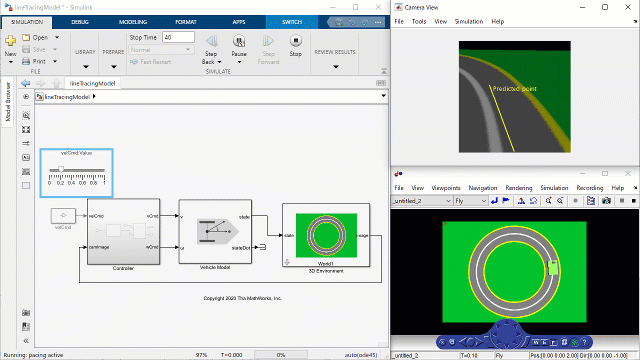

PDFのドキュメントは[こちら](matlab:open('AI_Robotics_Workshop_jp.pdf'))です。

[English version](matlab:open('workshopMenu.mlx'))

## 事前準備

MATLAB R2021a以降で下記のToolboxが必要

- [MATLAB](https://www.mathworks.com/products/matlab.html)

- [Simulink](https://www.mathworks.com/products/simulink.html)

- [Image Processing Toolbox](https://www.mathworks.com/products/image.html)

- [Computer Vision Toolbox](https://www.mathworks.com/products/computer-vision.html)

- [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html)

- [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html)

- [Robotics System Toolbox](https://www.mathworks.com/products/robotics.html)

- [Simulink 3D Animation](https://jp.mathworks.com/products/3d-animation.html?requestedDomain=)

アドオンとしてResNet18の学習済みモデルが必要

- Deep Learning Toolbox Model for ResNet-18 Network 

下記コマンドでエラーが出る場合は表示されるリンクから入手

resnet18

## シミュレーション編

### 1. 学習用の動画を生成

[genCourseTraj_jp.mlx](matlab:open('genCourseTraj_jp.mlx')) を開いて学習用の動画を生成

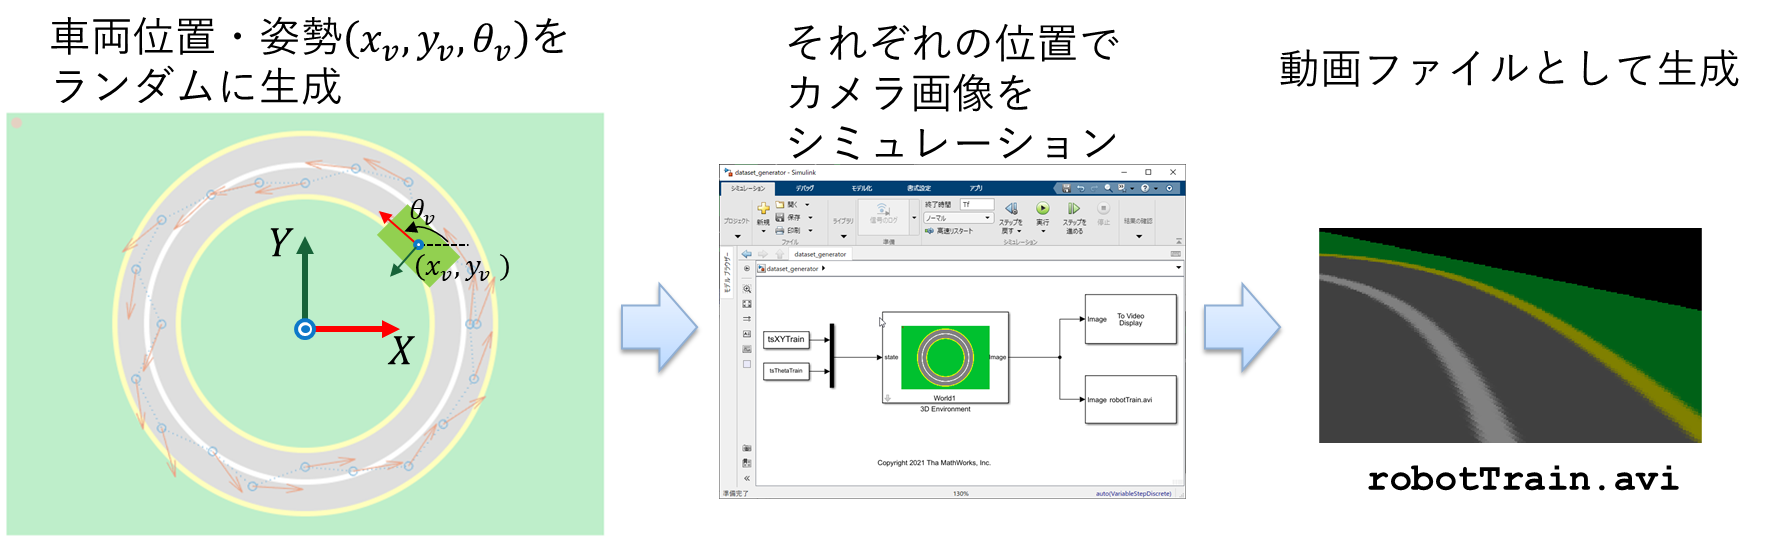

### 2. 動画のラベリング(アノテーション)

[annotateVideo_jp.mlx](matlab:open('annotateVideo_jp.mlx')) を開いて動画上の目標座標をラベリングする

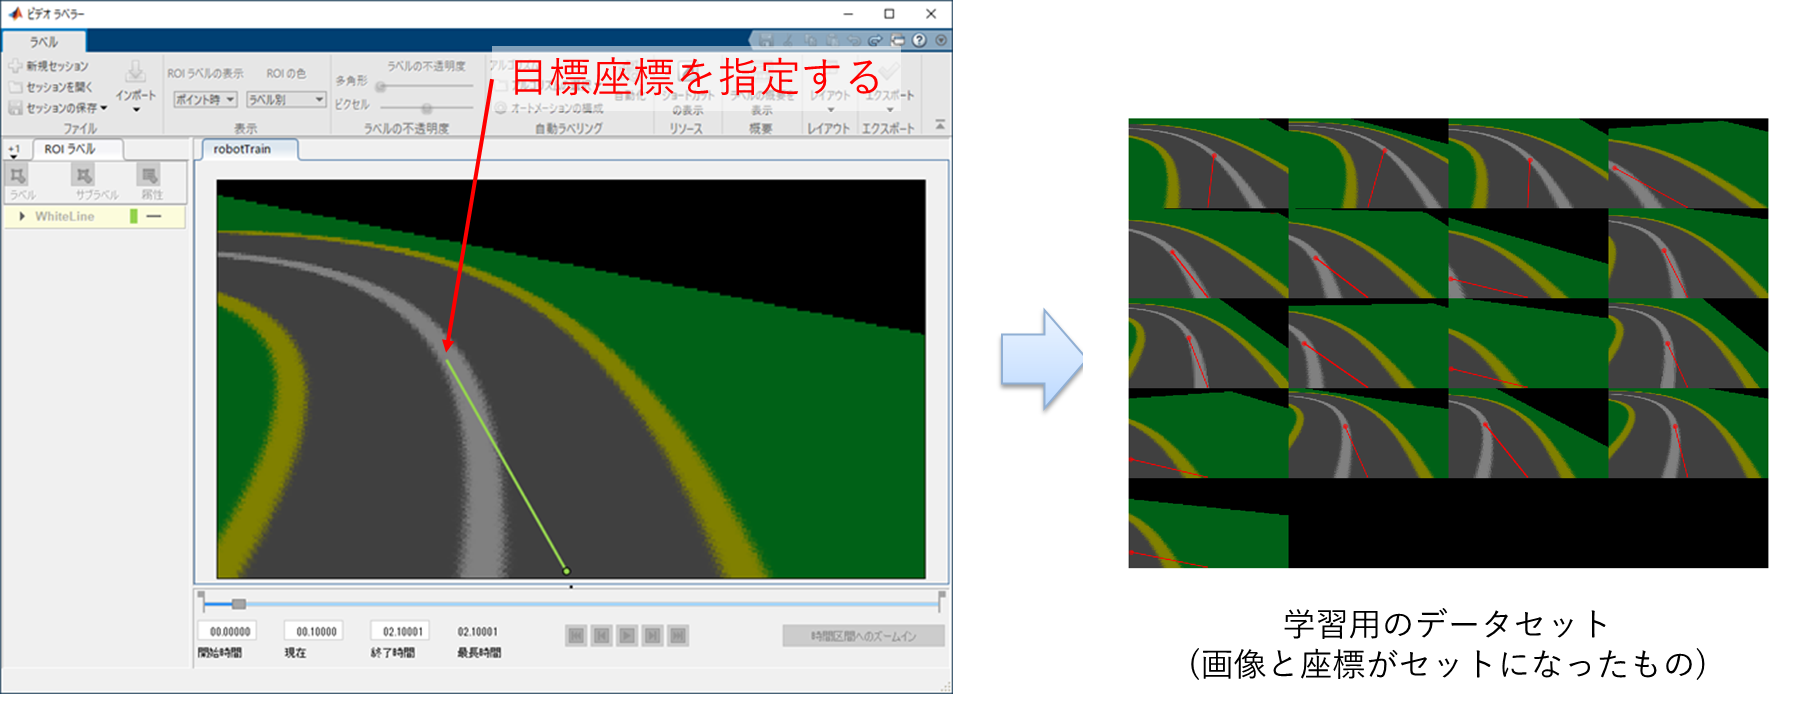

### 3. 回帰ネットワークの構築と学習

[trainWhiteLine_jp.mlx](matlab:open('trainWhiteLine_jp.mlx')) を開いて目標座標を推定するネットワークを学習

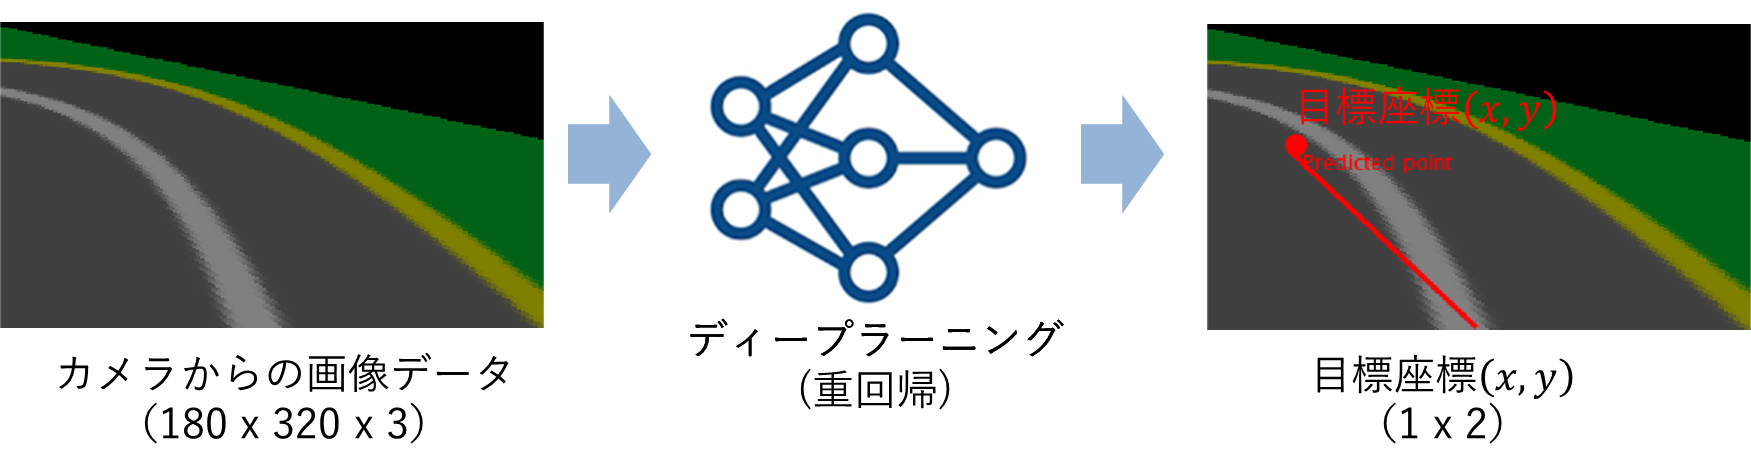

### 4. システムシミュレーションでライントレースの動作確認

[line_follower.slx](matlab:open('line_follower.slx')) を開いて学習済みのネットワークを使ってライントレースを実行する

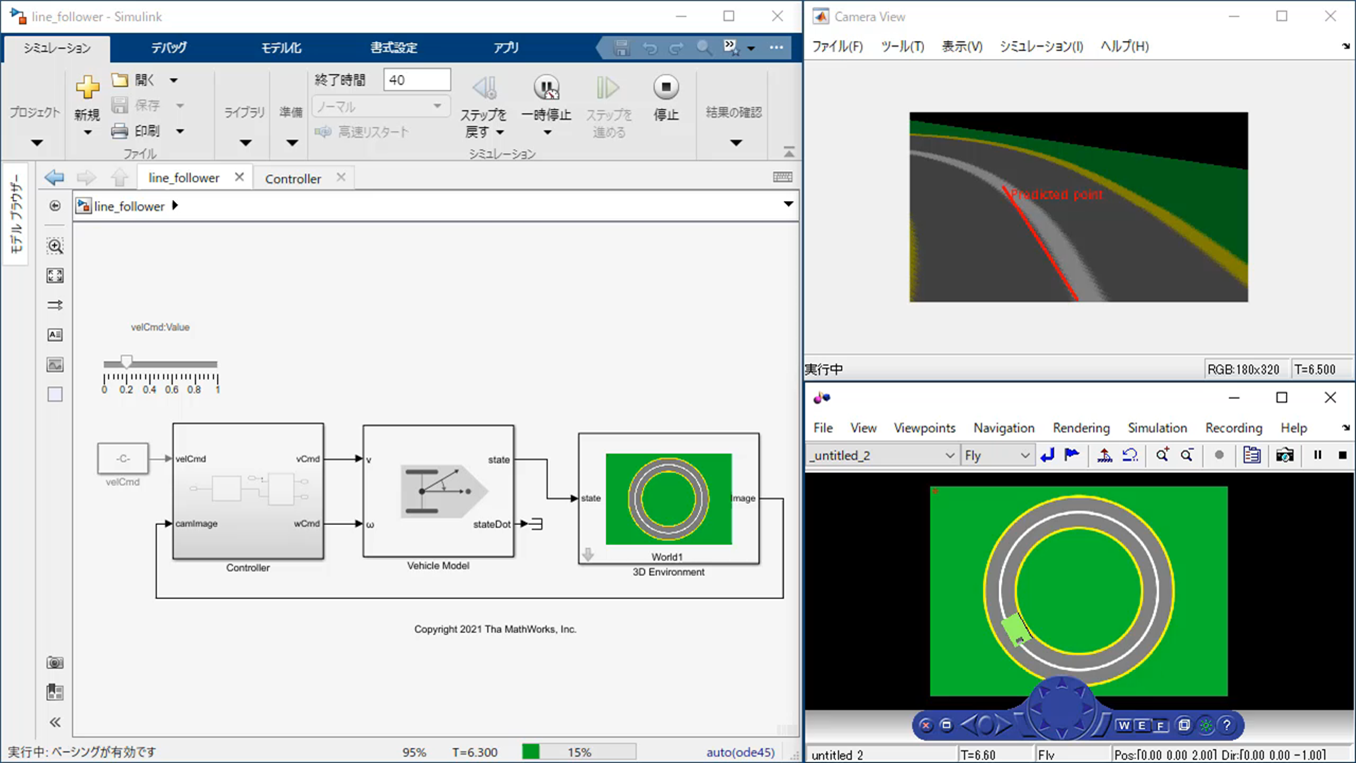

## ハードウェア実装編

### 1.ROS接続で実機から学習画像を収集

[teleopTestJetBot_jp.mlx](matlab:open('teleopTestJetBot_jp.mlx')) を開いてROS経由でハードウェアに接続し、学習用の追加画像を収集

### 2. ライン検出器を改善

[trainWhiteLineWithHardware_jp.mlx](matlab:open('trainWhiteLineWithHardware_jp.mlx')) を開いて、収集した画像を使って検出器を改善

### 3. ハードウェア接続でアルゴリズムをテスト

[testLineFollowerWithROS_jp.mlx](matlab:open('testLineFollowerWithROS_jp.mlx')) を開いてハードウェアとROS接続し、アルゴリズムをテスト

### 4. コード生成によるスタンドアローン実装

[deployLineFollower_jp.mlx](matlab:open('deployLineFollower_jp.mlx')) を開いてアルゴリズムをJetBotに実装し、スタンドアローンで動作を確認する

*Copyright 2021 The MathWorks, Inc.*